# Weighting Functions - Effective level of Emission and Absorption

clear variables

## Let's construct a simple atmosphere

% set up a simple atmosphere

z = linspace(0,100000,300);       % m - height in the atmosphere

% density decrease exponentially with height in an isothermal atmosphere!

T0 = 300;                        % K - temperature of atmosphere is constant with height

% need the specific gas constant for air
R = 8.314;                         % Pa * m^3/(mol K) - universal gas constant
m_air = 0.02897;                    % kg/mol - molar mass of air

R_air = R/m_air ;                     % J/(kg K) - specific gas constant of air

% We need to assume some surface pressure
P0 = 1e5;                        % Pa - surface pressure
rho0 = P0/(R_air * T0);               % kg/m^3 - density at the surface

% finally, we need a scale height
g0 = 9.81;                          % m/s^2 - surface gravity

H = R_air*T0/g0;                      % m - scale height

% now we can define the density as a function of height
rho = rho0*exp(-z/H);

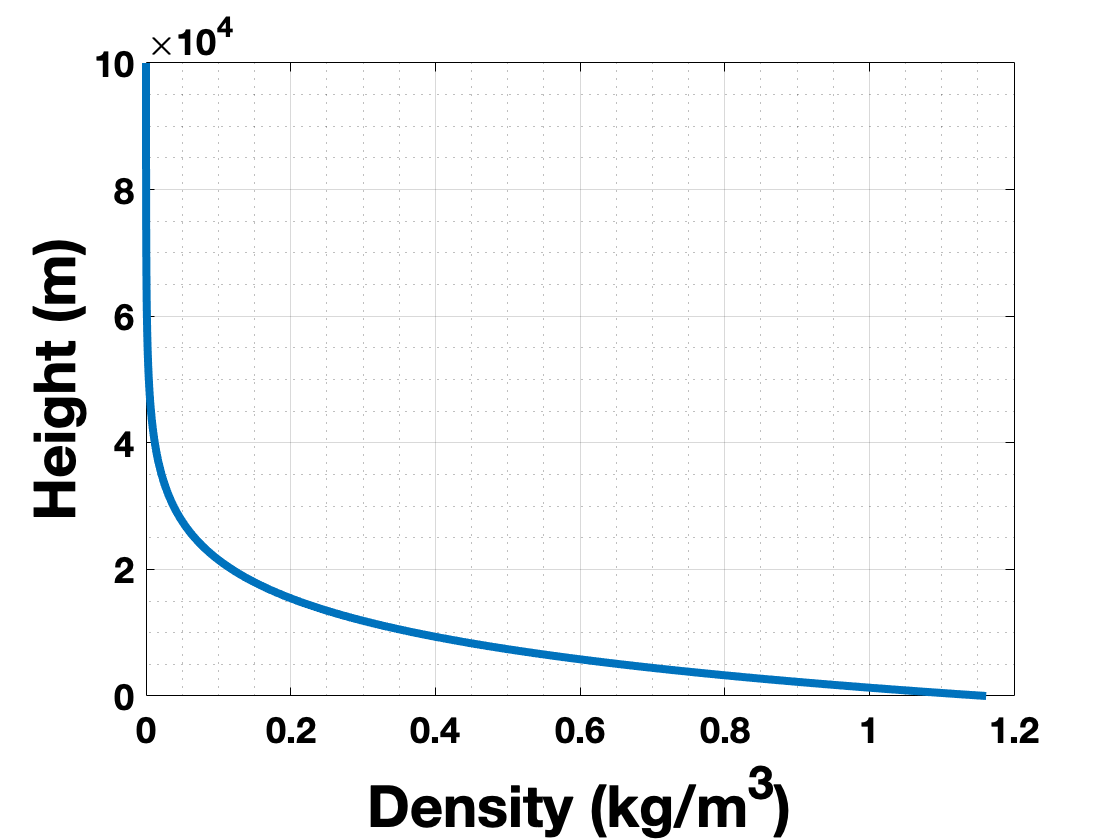

% Lets plot it!

figure; plot(rho,z); grid on; grid minor
xlabel('Density (kg/m^3)')
ylabel('Height (m)')

## Compute the weighting function with multiple K's

% lets assume some value for the mass absorption coefficient

k_m_lambda = logspace(-5,0,100);                          % m^2/kg  - mass absorption coefficient


% create zero vectors
Tau = zeros(length(z) - 1,length(k_m_lambda));         % optical depth
w = zeros(length(z) - 1,length(k_m_lambda));   % weighting functions

for jj = 1:length(k_m_lambda)

    for ii = (length(z)-1):(-1):1

        z_interval = z(ii:end);                  % interval of z to integrate over
        integrand = k_m_lambda(jj) * rho(ii:end);    % interval of density
        Tau(length(z) - ii,jj) = trapz(z_interval,integrand);  % optical depth from 0 to z(ii)

    end

    % Tau is defined from top to bottom. So we need to flip the density to be
    % oriented the same way
    w(:,jj) = k_m_lambda(jj) * exp(-Tau(:,jj)).*flipud(rho(1:end-1)');             % 1/m -  weighting funciton

end


## Plot Weighting Functions

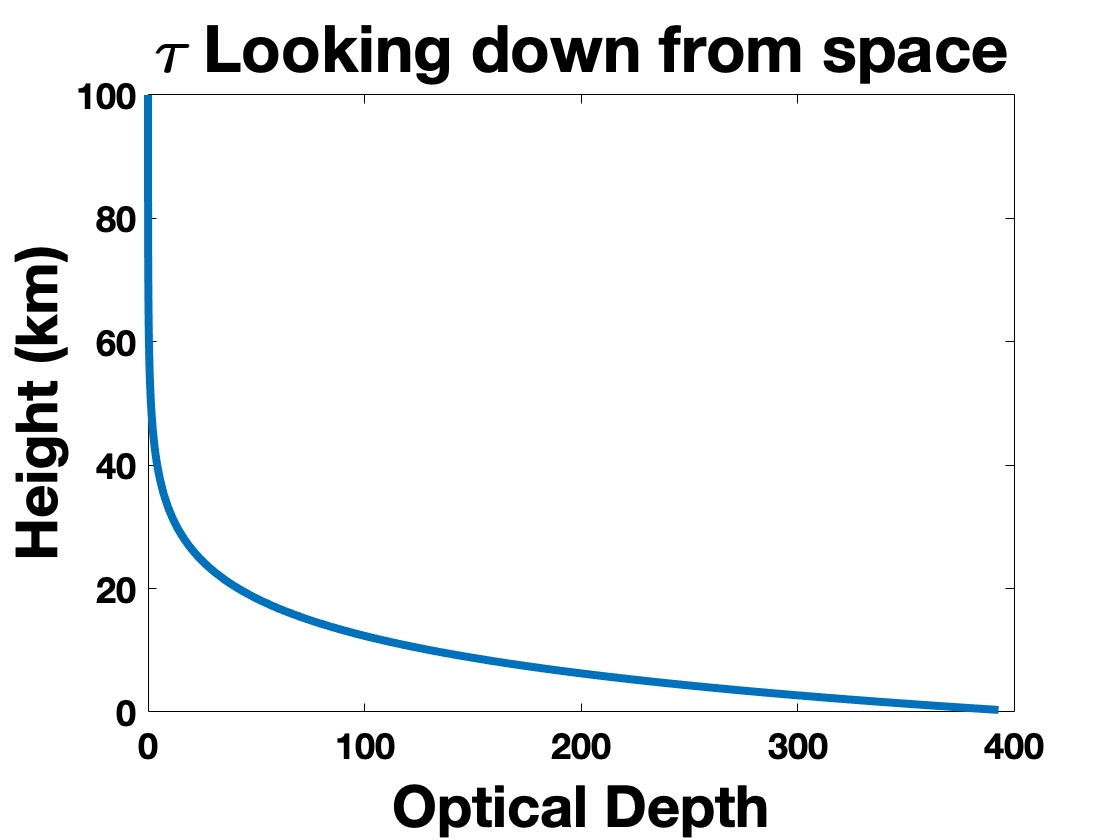

% Plot optical depth
idx = 72;

figure; plot(Tau(:,idx),fliplr(z(2:end))./1e3)
xlabel('Optical Depth')
ylabel('Height (km)')
title('\tau Looking down from space')

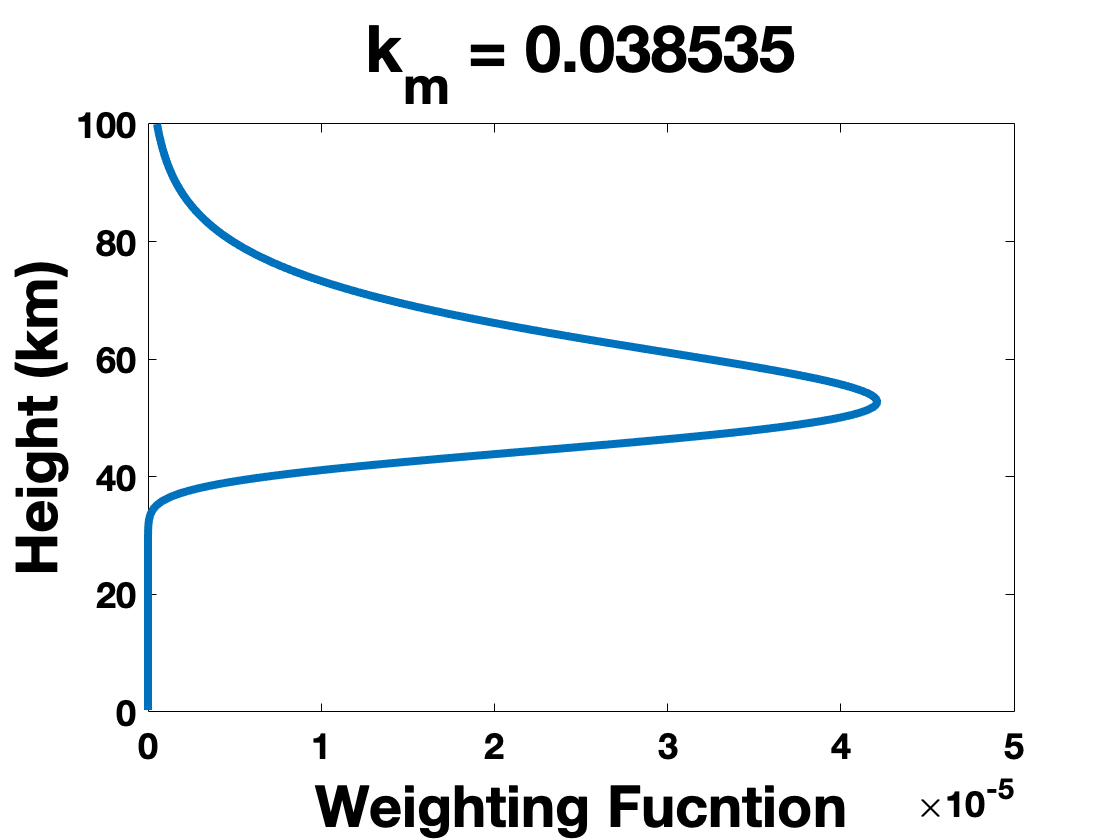

% Plot weighting function


figure; plot(w(:,idx),fliplr(z(2:end))./1e3)
xlabel('Weighting Fucntion')
ylabel('Height (km)')
title(['k_{m} = ', num2str(k_m_lambda(idx))])

% Combine the two above plots in 1

new_z = fliplr(z(2:end)); % This is the flipped z we will use for plotting
t = tiledlayout(1,1);

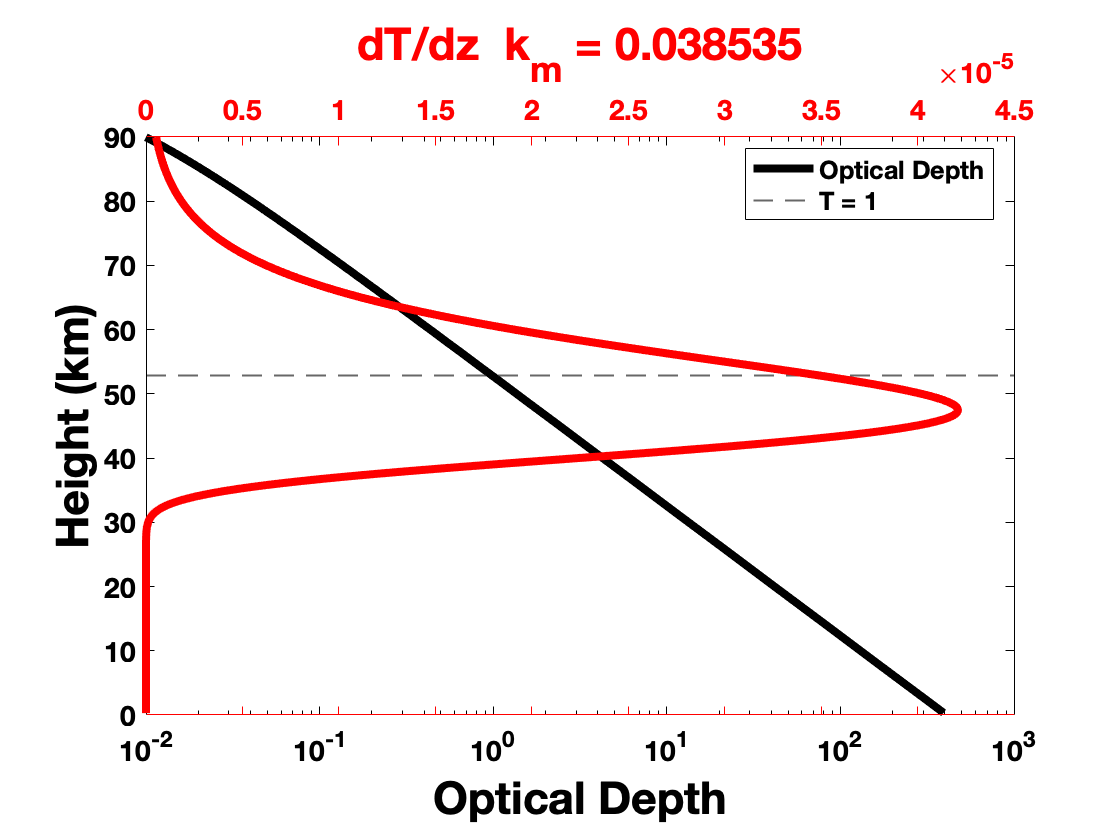

t = tiledlayout(1,1);
ax1 = axes(t);
semilogx(ax1,Tau(:,idx),new_z./1e3,'-k')
hold on
% compute the height where tau = 1
diff_1 = abs(Tau(:,idx) - 1);  % find tau value closest to 1
[val,min_index] = min(diff_1); % minimum value index
yline(ax1,new_z(min_index)/1e3,'Linewidth',1,'LineStyle','--')  % plot horizontal line at the height where tau =1
ax1.XColor = 'k';
ax1.YColor = 'k';
ax1.XLim = [1e-2 1e3];
ax1.XLabel.String = 'Optical Depth';
ax1.YLabel.String = 'Height (km)';
ax1.FontSize = 14;
legend('Optical Depth','T = 1','Location','best')

ax2 = axes(t);
plot(ax2,w(:,idx),new_z./1e3,'-r')
ax2.FontSize = 14;
ax2.YAxis.TickLength = [0 0];
ax2.YTickLabel = [];
ax2.YLim = [0 100];
ax2.XColor = 'r';
ax2.XAxisLocation = 'top';
ax2.Color = 'none';
ax2.XLabel.String = ['dT/dz  k_{m} = ',num2str(k_m_lambda(idx))];

%ax2.YLabel.String = 'Height (km)';
%legend('Weighting Function','Location','best')

## Create a GIF!

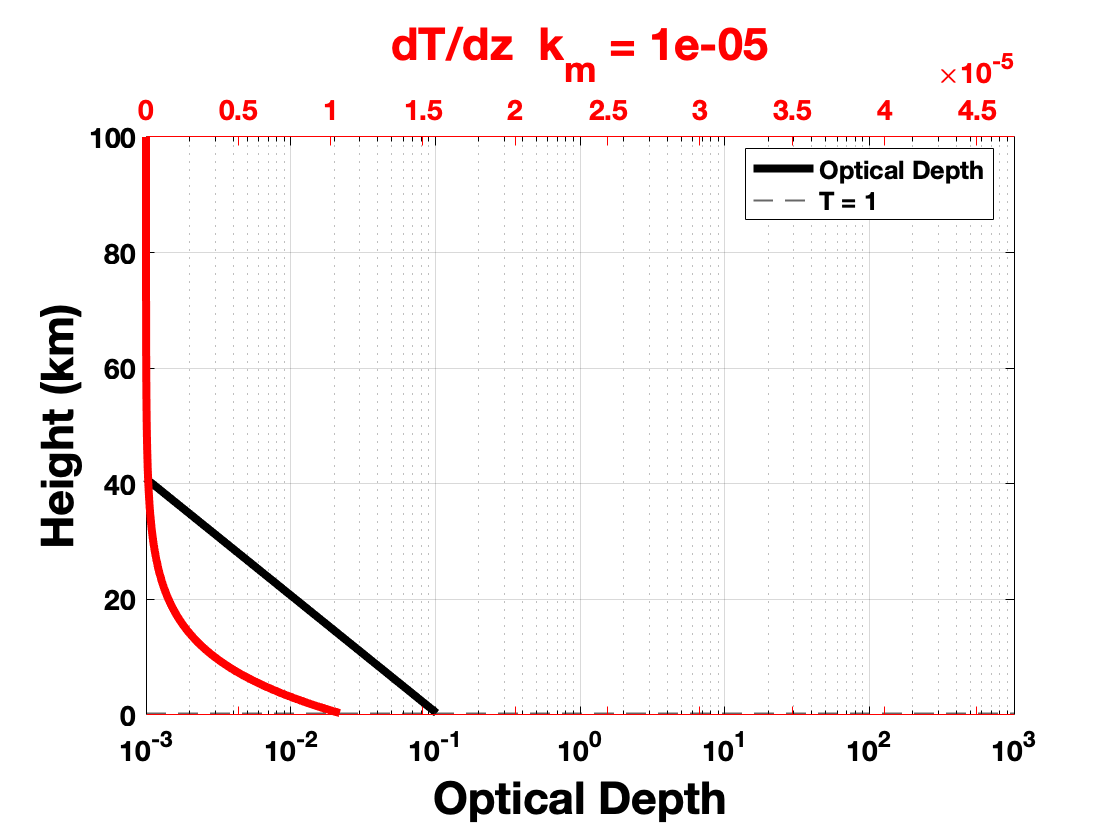

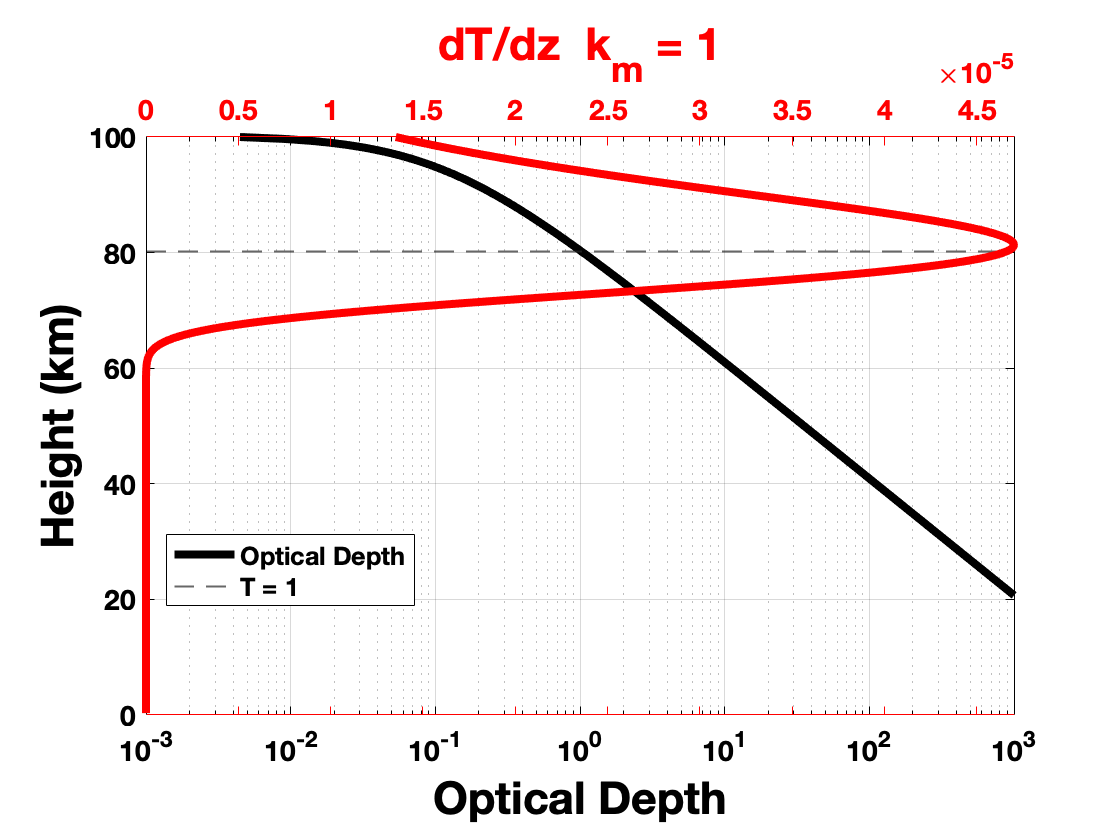

%max_x1_lim = max(Tau,[],'all');
max_w_lim = max(w,[],'all');
h = figure;
axis tight manual % this ensures that getframe() returns a consistent size
filename = 'w_changing_k.gif';

for n = 1:length(k_m_lambda)

    t = tiledlayout(1,1);
    ax1 = axes(t);
    semilogx(ax1,Tau(:,n),new_z./1e3,'-k')
    hold on
    % compute the height where tau = 1
    diff_1 = abs(Tau(:,n) - 1);  % find tau value closest to 1
    [val,min_index] = min(diff_1); % minimum value index
    yline(ax1,new_z(min_index)/1e3,'Linewidth',1,'LineStyle','--')  % plot horizontal line at the height where tau =1
    ax1.XColor = 'k';
    ax1.YColor = 'k';
    ax1.XGrid = 'on';
    ax1.YGrid = 'on';
    ax1.YLim = [0 100];
    ax1.XLim = [1e-3 1e3];
    ax1.XLabel.String = 'Optical Depth';
    ax1.YLabel.String = 'Height (km)';
    legend('Optical Depth','T = 1','Location','best')
    ax1.FontSize = 14;

    ax2 = axes(t);
    plot(ax2,w(:,n),new_z./1e3,'-r')
    ax2.YAxis.TickLength = [0 0];
    ax2.YTickLabel = [];
    ax2.YLim = [0 100];
    ax2.XLim = [0 max_w_lim];
    ax2.XColor = 'r';
    ax2.XAxisLocation = 'top';
    ax2.Color = 'none';
    ax2.XLabel.String = ['dT/dz  k_{m} = ',num2str(k_m_lambda(n))];
    ax2.FontSize = 14;

    drawnow
    % Capture the plot as an image
    frame = getframe(h);
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,256);
    % Write to the GIF File
    if n == 1
        imwrite(imind,cm,filename,'gif', 'Loopcount',inf);
    else
        imwrite(imind,cm,filename,'gif','WriteMode','append');
    end
end

## Compute the weighting function with 1 k

% lets assume some value for the mass absorption coefficient

k_m_lambda = 1e-1;                          % m^2/kg  - mass absorption coefficient


% create zero vectors
Tau = zeros(length(z) - 1,length(k_m_lambda));         % optical depth



for ii = (length(z)-1):(-1):1

    z_interval = z(ii:end);                  % interval of z to integrate over
    integrand = k_m_lambda * rho(ii:end);    % interval of density
    Tau(length(z) - ii) = trapz(z_interval,integrand);  % optical depth from 0 to z(ii)

end

% Tau is defined from top to bottom. So we need to flip the density to be
% oriented the same way
w = k_m_lambda * exp(-Tau).*flipud(rho(1:end-1)');             % 1/m -  weighting funciton



## Plot Weighting Functions

% Plot optical depth


figure; plot(Tau,fliplr(z(2:end))./1e3)
xlabel('Optical Depth')
ylabel('Height (km)')
title('\tau Looking down from space')
% Plot weighting function


figure; plot(w,fliplr(z(2:end))./1e3)
xlabel('Weighting Fucntion')
ylabel('Height (km)')
title(['k_{m} = ', num2str(k_m_lambda)])

## Plot Movie of Weighting Function!


figure;

for ii = 1:length(k_m_lambda)

    plot(w(ii),fliplr(z(2:end))./1e3)
    xlabel('Weighting Fucntion')
    ylabel('Height (km)')
    grid on; grid minor
    pause(0.3)

end


